# **Normalised Cut and Image Segmentation**

**Mathematics for Computing - 4**

Team C - 12

- Subash B (CB.SC.U4AIE24254)

- Sai Kushal Boggarapu (CB.SC.U4AIE24252)

- Naveen K (CB.SC.U4AIE24235)

- Cibikumar B (CB.SC.UA4IE24212)

## 1. Introduction

Image segmentation is the process of dividing an image into multiple regions or objects that share common features such as brightness, color, or texture. Traditional segmentation methods like thresholding, region growing, or clustering often fail in complex images where objects have **gradual intensity changes, overlapping regions, or textured backgrounds**.

To address these challenges, **Shi and Malik (2000)** proposed the **Normalized Cut (Ncut) method**, a graph-based spectral image segmentation technique. The main idea is to represent the image as a **graph**, where pixels are nodes and similarity between pixels forms the edges. Unlike simple cuts, which often favor **small isolated regions**, Ncut introduces a **normalization term** to balance the partition sizes and produce meaningful segmentation.

In essence: **group pixels that are similar and separate pixels that are dissimilar**, while keeping partitions balanced.

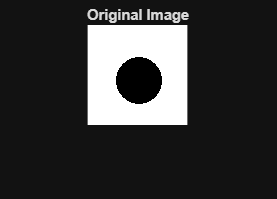

clear; clc; close all;

I = imread('img.png');
I = im2double(I);

if size(I,3)==3
    grayI = rgb2gray(I);
else
    grayI = I;
end

I = imresize(I,[100 100]);
grayI = imresize(grayI,[100 100]);

figure; imshow(I); title('Original Image');

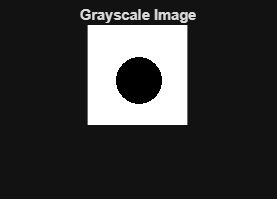

figure; imshow(grayI); title('Grayscale Image');


[h,w] = size(grayI);
N = h*w;

disp(['Image size: ', num2str(h),' x ', num2str(w)]);

Image size: 100 x 100


disp(['Total pixels (nodes): ', num2str(N)]);

Total pixels (nodes): 10000


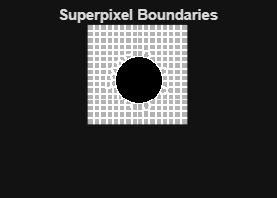

%% SUPERPIXEL OVERSEGMENTATION

numSuperpixels = 250;

[L, numLabels] = superpixels(I, numSuperpixels);

figure
imshow(boundarymask(L).*I + I*0.7)
title('Superpixel Boundaries')


disp(['Superpixels: ', num2str(numLabels)]);

Superpixels: 256


%% SUPERPIXEL FEATURES

spColor = zeros(numLabels,3);
spPos   = zeros(numLabels,2);

for i = 1:numLabels

    mask = L==i;

    for c = 1:3
        temp = I(:,:,c);
        spColor(i,c) = mean(temp(mask));
    end

    [y,x] = find(mask);
    spPos(i,:) = [mean(y) mean(x)];

end

## **2. Representing the Image as a Graph**

In Ncut, the image is transformed into a **weighted undirected graph**:


$$G=\left(V,E\right)$$


- **Nodes **$V$: Each pixel of the image is treated as a node

- **Edges **$E$: Connect pairs of pixels

- **Edge weights **$w_{ij}$: Measure similarity between pixels $i$ and $j$

**2.1 Edge Weight**

A commonly used weight function combines **brightness similarity** and **spatial closeness**:


$$w_{ij} = \begin{cases}  \exp\Big(-\frac{||F(i)-F(j)||^2}{2\sigma_I^2}\Big) \cdot \exp\Big(-\frac{||X(i)-X(j)||^2}{2\sigma_X^2}\Big), & ||X(i)-X(j)|| < r \\ 0, & \text{otherwise}  \end{cases}$$


Where:

- $F(i)$ → feature vector of pixel $i$ (brightness, color, texture)

- $X(i)$ → spatial coordinates of pixel $i$

- $\sigma_I$, $\sigma_X$ → parameters controlling sensitivity to feature differences and spatial distance

- $r$ → neighborhood radius to limit edges to local regions

**Intuition:** Pixels that are **similar in appearance and close together** have higher weights → more likely to belong to the same segment.

%% SUPERPIXEL GRAPH

sigma_I = 0.1;
sigma_X = 15;

rows = [];
cols = [];
vals = [];

for i = 1:numLabels
for j = i+1:numLabels

    dColor = norm(spColor(i,:) - spColor(j,:))^2;
    dSpace = norm(spPos(i,:) - spPos(j,:))^2;

    w = exp(-dColor/(2*sigma_I^2)) * exp(-dSpace/(2*sigma_X^2));

    if w > 0.001
        rows = [rows;i;j];
        cols = [cols;j;i];
        vals = [vals;w;w];
    end

end
end

W = sparse(rows,cols,vals,numLabels,numLabels);

**2.2 Degree Matrix**

For each node $i$, the **degree** is the sum of all edge weights connected to it:


$$d_i = \sum_j w_{ij}$$


The **degree matrix** $D$ is a diagonal matrix:


$$D = \text{diag}(d_1, d_2, \dots, d_n)$$


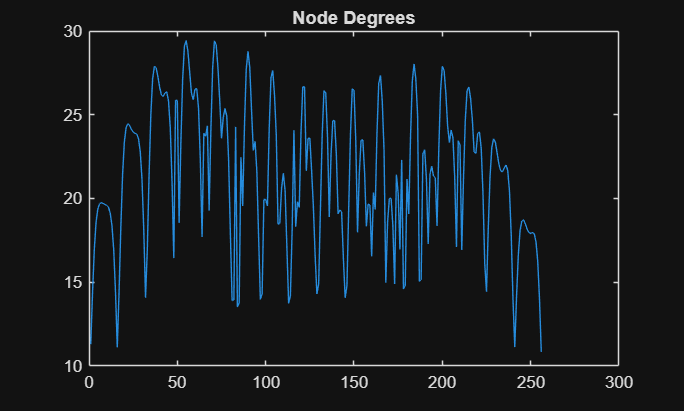

d = sum(W,2);
D = spdiags(d,0,numLabels,numLabels);
figure;
plot(d);
title('Node Degrees');

## **3. Standard Cut vs Normalized Cut**

**3.1 Standard Graph Cut**

A standard graph cut divides the graph into two disjoint sets $A$ and $B$ and is defined as:


$$\text{cut}(A,B) = \sum_{i \in A, j \in B} w_{ij}$$


- Measures the total connection between two sets

- Limitation: favors **small isolated sets** because it only considers edge weights across the cut

**3.2 Normalized Cut (Ncut)**

Normalized Cut introduces **normalization** to balance partitions:


$$\text{Ncut}(A,B) = \frac{\text{cut}(A,B)}{\text{assoc}(A,V)} + \frac{\text{cut}(A,B)}{\text{assoc}(B,V)}$$


Where:


$$\text{assoc}(A,V) = \sum_{i \in A, j \in V} w_{ij}, \quad \text{assoc}(B,V) = \sum_{i \in B, j \in V} w_{ij}$$


- Minimizing Ncut produces partitions with **high similarity within groups** and **low similarity between groups**

- Prevents the algorithm from isolating small trivial segments

## 4. Formulation as a Minimization Problem

4.1 Indicator Vector

Define an indicator vector $y$ for nodes:


$$y_i = \begin{cases}  1, & i \in A \\ -1, & i \in B \end{cases}$$


The **cut** can be rewritten in matrix form using the **graph Laplacian **$L = D - W$:


$$\text{cut}(A,B) = \frac{1}{4} y^T (D-W) y$$


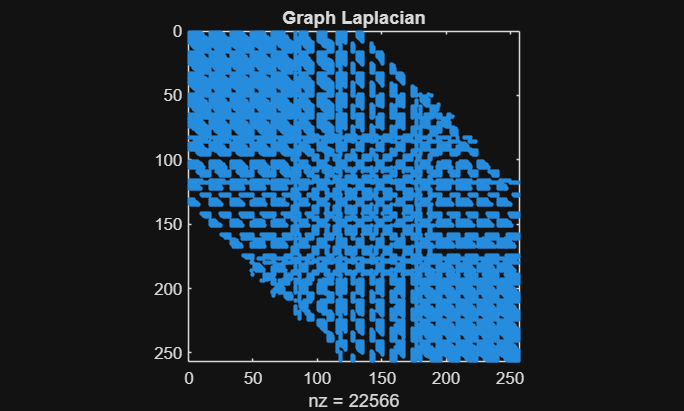

L = D - W;

figure; spy(L);
title('Graph Laplacian');

**4.2 Ncut as Rayleigh Quotient**

Normalized Cut can be expressed as:


$$\text{Ncut}(A,B) = \frac{y^T (D-W) y}{y^T D y}$$


- This is a **Rayleigh quotient**

- **Goal:** Minimize Ncut → balanced partition

**4.3 Relaxation to Continuous Problem**

- Exact minimization with $y_i = \pm 1$ is **NP-hard**

- Relax $y$ to take **continuous real values**, leading to a **generalized eigenvalue problem**:


$$(D - W) y = \lambda D y$$


- Constraint $y^T D \mathbf{1} = 0$ ensures **balanced partitions**

- The solution $y$ is continuous → the **second smallest eigenvector** (Fiedler vector) approximates the optimal discrete partition

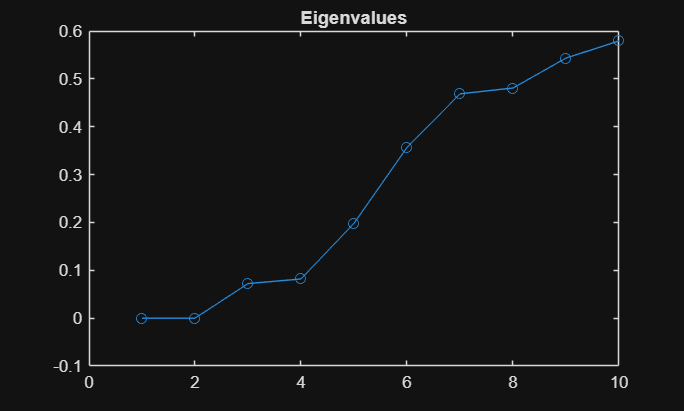

numEig = 10;

[eigVecs, eigVals] = eigs(L,D,numEig,'smallestabs');

eigVals = diag(eigVals);

figure
plot(eigVals,'-o')
title('Eigenvalues')

## 5. Partitioning Using Eigenvectors

- Solve $(D - W) y = \lambda D y$

- Use **second smallest eigenvector** $y_2$ for partition

- Threshold eigenvector values (0, median, or optimal Ncut value) → assign nodes to **A or B**

- Recursively apply the process on each subgraph → multiple regions

**Optional:** K-way partitioning uses **top k eigenvectors** and **k-means clustering** to assign pixels to multiple regions simultaneously.**6. Computational Complexity and Lanczos Method**

- **Direct eigenvalue decomposition** → $O(n^3)$, impractical for large images (millions of pixels)

- Observations for optimization:

- Graphs are **locally connected → sparse matrices**

- Only **top few eigenvectors** are needed

- **Precision can be low** → approximate eigenvectors suffice

- **Solution:** Use **Lanczos algorithm**, which efficiently computes top eigenvectors of **sparse matrices**.

**6.1 Time Complexity with Lanczos**

- Let nnn = number of nodes (pixels)

- Let mmm = number of matrix-vector iterations needed

- Let $M(n)$ = cost of matrix-vector multiplication


$$\text{Time complexity} = O(m M(n))$$


- Sparse graph → $M(n) = O(n)$

- Empirically, $m \sim O(\sqrt{n})$

- So total time complexity ≈ $O(n \sqrt{n})$, much faster than $O(n^3)$

gaps = diff(eigVals);

[~,k] = max(gaps);

disp(['Estimated number of segments: ',num2str(k)]);

Estimated number of segments: 5


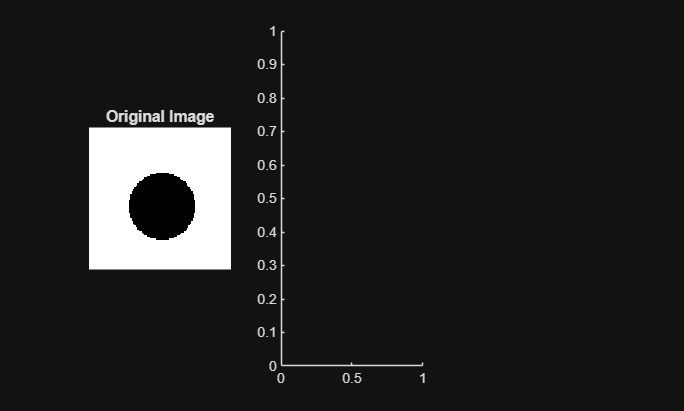


%% SPECTRAL CLUSTERING

Y = bsxfun(@rdivide,eigVecs(:,1:k), sqrt(sum(eigVecs(:,1:k).^2,2))+eps);

labels = kmeans(Y,k,'Replicates',10);

seg = zeros(size(L));

for i=1:numLabels
    seg(L==i) = labels(i);
end

figure
subplot(1,3,1)
imshow(I)
title('Original Image')

subplot(1,3,2)

imshow(boundarymask(L).*I + I*0.7)

Error using boundarymask
Expected input to be nonnegative.

Error in boundarymask (line 36)
validateattributes(L,{numericTypes{:},'logical'},...
^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

title('Superpixels')

subplot(1,3,3)
imshow(label2rgb(seg,'jet','k','shuffle'))
title('Final Segmentation')

## 7. K-Way Cut

- **Problem:** Recursive 2-way splitting only uses the second smallest eigenvector and can be slow if we want many segments.

- **Solution:** Use **top k eigenvectors** to partition the image into **K segments directly**.

**Steps (simple):**

- Compute the **top k eigenvectors** from the graph Laplacian.

- Represent each pixel as a **k-dimensional vector** using these eigenvectors.

- Cluster the pixels using a **simple clustering method** like **k-means** → gives **initial segments**.

- Refine segments if needed by merging small clusters using **Ncut criterion**.

**Key idea:**

- Each eigenvector provides extra information about how the image can be split.

- Using multiple eigenvectors together helps **get all segments at once**, instead of splitting one by one.

**Example:**

- Want 3 segments → use 3 top eigenvectors

- Each pixel gets 3 numbers from these eigenvectors

- k-means clusters the pixels into 3 groups → final segments

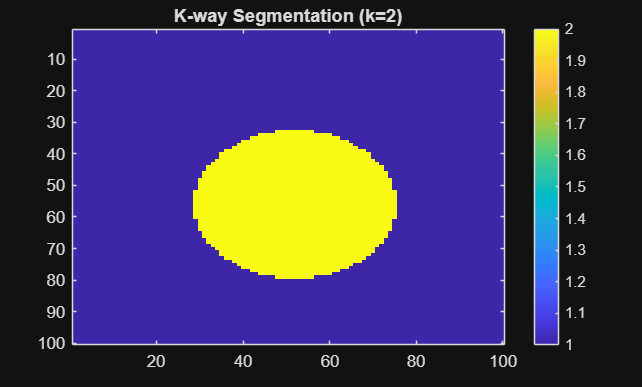

k = 2;
[eigVecs_k, ~] = eigs(L,D,k,'smallestabs');
Y = bsxfun(@rdivide,eigVecs_k, sqrt(sum(eigVecs_k.^2,2))+eps);
labels_k = kmeans(Y,k,'Replicates',5);
segK = reshape(labels_k,h,w);

figure;
imagesc(segK);
colorbar;
title(['K-way Segmentation (k=',num2str(k),')']);

Segmentation Overlay

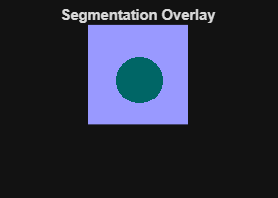

figure;
imshow(I); hold on;
hSeg = imshow(label2rgb(segK));
set(hSeg,'AlphaData',0.4);
title('Segmentation Overlay');

Evaluation

disp('--- Final Report ---');

--- Final Report ---


disp(['Number of segments (recursive): ', num2str(max(labels))]);

Number of segments (recursive): 42


disp(['Number of segments (K-way): ', num2str(k)]);

Number of segments (K-way): 2


disp(['Final Ncut value: ', num2str(ncut_val)]);

Final Ncut value: 0.67194


disp('Ncut segmentation completed successfully.');

Ncut segmentation completed successfully.


## 8. Advantages and Applications

Advantages:

- Produces **balanced, meaningful partitions**

- Works on **arbitrary shapes and textures**

- Automatically determines the number of segments (recursive splitting)

- Can be accelerated using **sparse matrices and Lanczos solver**

**Applications:**

- Medical image segmentation (organs, tumors)

- Object recognition in computer vision

- Video segmentation

- Satellite or remote sensing image analysis

## 9. Conclusion

The **Normalized Cut algorithm** is a **mathematically rigorous, graph-based method** for image segmentation. Its key steps are:

- Convert image → weighted graph

- Solve generalized eigenvalue problem to approximate partition

- Minimize **Normalized Cut criterion** to find optimal split

- Recursively partition image into multiple regions

By using **sparse graphs** and the **Lanczos method**, the Ncut algorithm becomes computationally feasible for large images. Its combination of **eigenvector-based partitioning** and **normalized cut minimization** makes it a cornerstone technique in modern computer vision.